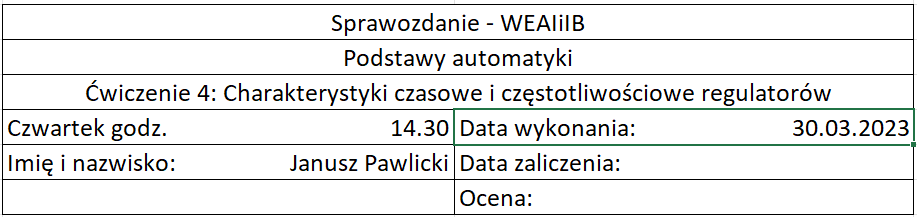

## 1. Wstęp

Celem ćwiczenia jest zapoznanie się z charakterystykami czasowymi i częstotliwościowymi podstawowych typów regulatorów ciągłych, omawianych na wykładzie i podczas ćwiczeń audytoryjnych. Podczas ćwiczenia należy zbadać następujące regulatory:

#### a) Regulator PI o transmitancji:

#### b) Regulator PD rzeczywisty o transmitancji:

#### c) Regulator PID rzeczywisty o transmitancji:

## 2. Przebieg laboratorium

### 2.1 Regulator PI

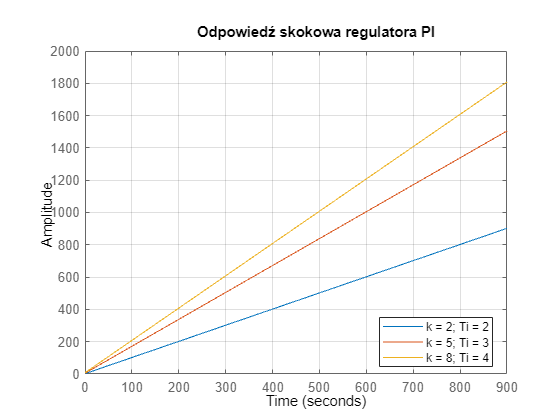

k1 = 2;
k2 = 5;
k3 = 8;
Ti1 = 2;
Ti2 = 3;
Ti3 = 4;

licz1 = [k1 * Ti1, k1];
mian1 = [Ti1, 0];
licz2 = [k2 * Ti2, k2];
mian2 = [Ti2, 0];
licz3 = [k3 * Ti3, k3];
mian3 = [Ti3, 0];

% Odpowiedź skokowa
figure()
hold on
step(licz1, mian1);
step(licz2, mian2);
step(licz3, mian3);
legend('k = 2; Ti = 2', 'k = 5; Ti = 3', 'k = 8; Ti = 4')
legend('Location','best')
title('Odpowiedź skokowa regulatora PI')
grid on
hold off

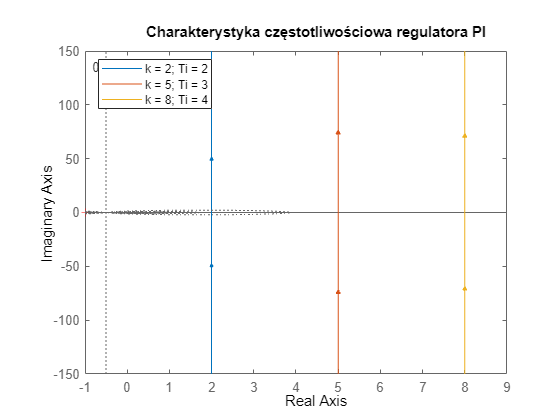


%Char nyq
figure()
hold on
nyquist(licz1, mian1);
nyquist(licz2, mian2);
nyquist(licz3, mian3);
grid on
title('Charakterystyka częstotliwościowa regulatora PI')
legend('k = 2; Ti = 2', 'k = 5; Ti = 3', 'k = 8; Ti = 4')
legend('Location','best')
hold off

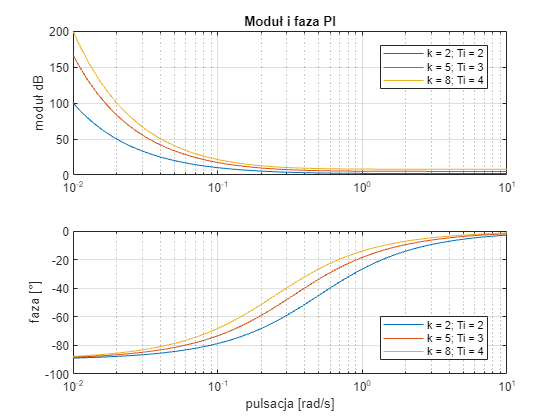


%Char Bode
[m1, p1, w1] = fbode(licz1, mian1);
[m2, p2, w2] = fbode(licz2, mian2);
[m3, p3, w3] = fbode(licz3, mian3);
figure()
subplot(2, 1, 1);
semilogx(w1, m1, w2, m2, w3, m3);
title('Moduł i faza PI')
ylabel('moduł dB');
legend('k = 2; Ti = 2', 'k = 5; Ti = 3', 'k = 8; Ti = 4');
legend('Location','best')
grid on;
subplot(2, 1, 2);
semilogx(w1, p1, w2, p2, w3, p3);
xlabel('pulsacja [rad/s]')
ylabel('faza [°]')
legend('k = 2; Ti = 2', 'k = 5; Ti = 3', 'k = 8; Ti = 4')
legend('Location','best')
grid on

### 2.2 Regulator PD

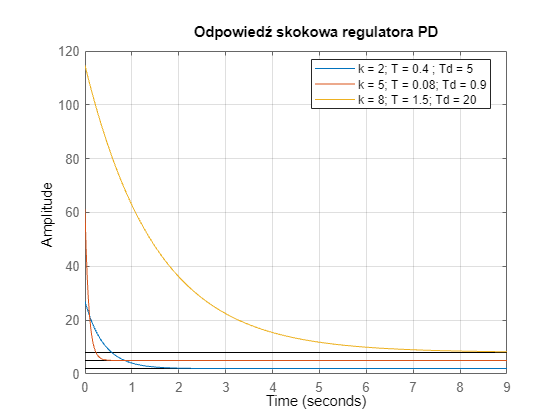

k1 = 2;
k2 = 5;
k3 = 8;
T1 = 0.4;
T2 = 0.08;
T3 = 1.5;
Td1 = 5;
Td2 = 0.9;
Td3 = 20;

licz1 = [k1 *(T1 + Td1), k1];
mian1 = [T1, 1];
licz2 = [k2 *(T2 + Td2), k2];
mian2 = [T2, 1];
licz3 = [k3 *(T3 + Td3), k3];
mian3 = [T3, 1];

% Odpowiedź skokowa
figure()
hold on
step(licz1, mian1);
step(licz2, mian2);
step(licz3, mian3);
legend('k = 2; T = 0.4 ; Td = 5', 'k = 5; T = 0.08; Td = 0.9', 'k = 8; T = 1.5; Td = 20')
legend('Location','best')
title('Odpowiedź skokowa regulatora PD')
grid on
hold off

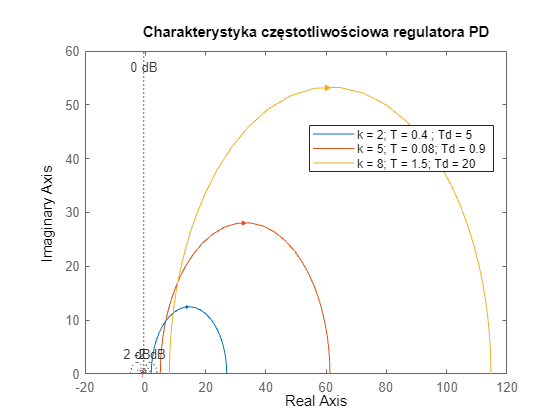


%Char nyq
figure()
hold on
G = tf(licz1, mian1);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G, plotoptions);
nyquist(licz2, mian2);
nyquist(licz3, mian3);
grid on
title('Charakterystyka częstotliwościowa regulatora PD')
legend('k = 2; T = 0.4 ; Td = 5', 'k = 5; T = 0.08; Td = 0.9', 'k = 8; T = 1.5; Td = 20')
legend('Location','best')
hold off

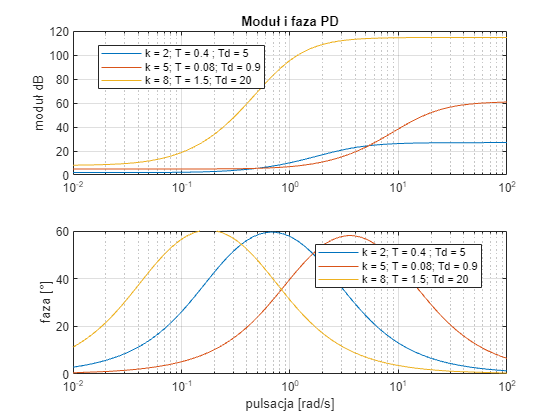


%Char Bode
[m1, p1, w1] = fbode(licz1, mian1);
[m2, p2, w2] = fbode(licz2, mian2);
[m3, p3, w3] = fbode(licz3, mian3);
figure()
subplot(2, 1, 1);
semilogx(w1, m1, w2, m2, w3, m3);
title('Moduł i faza PD')
ylabel('moduł dB');
legend('k = 2; T = 0.4 ; Td = 5', 'k = 5; T = 0.08; Td = 0.9', 'k = 8; T = 1.5; Td = 20');
legend('Location','best')
axis([1/100 100 0 120])
grid on;
subplot(2, 1, 2);
semilogx(w1, p1, w2, p2, w3, p3);
xlabel('pulsacja [rad/s]')
ylabel('faza [°]')
legend('k = 2; T = 0.4 ; Td = 5', 'k = 5; T = 0.08; Td = 0.9', 'k = 8; T = 1.5; Td = 20')
legend('Location','best')
axis([1/100 100 0 60])
grid on

Najlepsze dopasowanie otrzymujemy z modelu Kupfmullera II rzędu.

### 2.3 Regulator PID

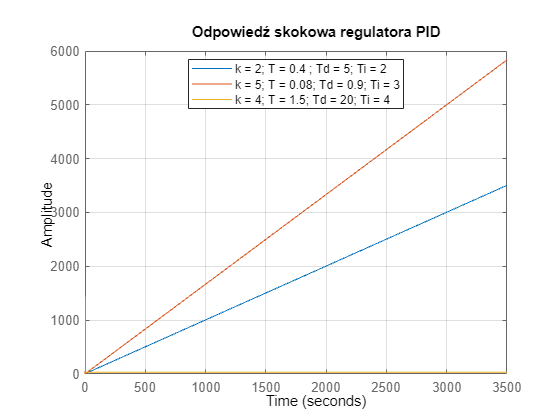

k1 = 2;
k2 = 5;
k3 = 4;
T1 = 0.4;
T2 = 0.08;
T3 = 1.5;
Td1 = 5;
Td2 = 0.9;
Td3 = 20;
Ti1 = 2;
Ti2 = 3;
Ti3 = 4;

licz1 = [k1 * Ti1 * (T1 + Td1), k1 * (T1 + Td1), k1];
mian1 = [Ti1 * T1, Ti1, 0];
licz2 = [k2 * Ti2 * (T2 + Td2), k2 * (T2 + Td2), k2];
mian2 = [Ti2 * T2, Ti2, 0];
licz3 = [k3 * Ti3 * (T3 + Td3), k3 * (T3 + Td3), k3];
mian3 = [Ti2 * T2, Ti2, 0];

% Odpowiedź skokowa
figure()
hold on
step(licz1, mian1);
step(licz2, mian2);
step(licz3, mian3);
legend('k = 2; T = 0.4 ; Td = 5; Ti = 2', 'k = 5; T = 0.08; Td = 0.9; Ti = 3', 'k = 4; T = 1.5; Td = 20; Ti = 4')
legend('Location','best')
title('Odpowiedź skokowa regulatora PID')
grid on
hold off

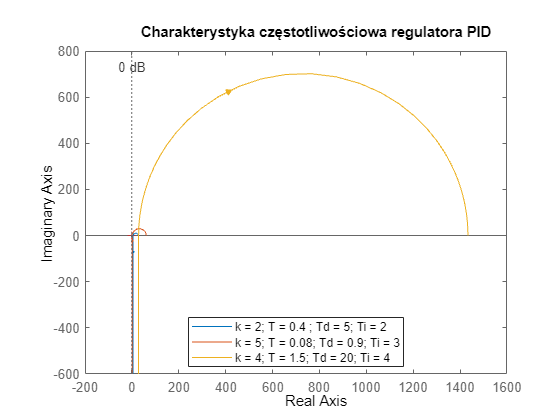


%Char nyq
figure()
hold on
G = tf(licz1, mian1);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G, plotoptions);
nyquist(licz2, mian2);
nyquist(licz3, mian3);
grid on
title('Charakterystyka częstotliwościowa regulatora PID')
legend('k = 2; T = 0.4 ; Td = 5; Ti = 2', 'k = 5; T = 0.08; Td = 0.9; Ti = 3', 'k = 4; T = 1.5; Td = 20; Ti = 4')
legend('Location','best')
hold off

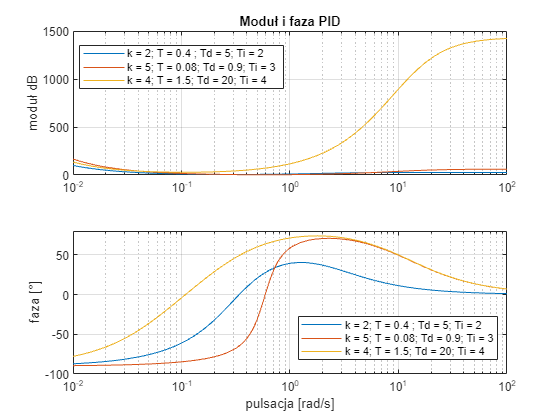


%Char Bode
[m1, p1, w1] = fbode(licz1, mian1);
[m2, p2, w2] = fbode(licz2, mian2);
[m3, p3, w3] = fbode(licz3, mian3);
figure()
subplot(2, 1, 1);
semilogx(w1, m1, w2, m2, w3, m3);
title('Moduł i faza PID')
ylabel('moduł dB');
legend('k = 2; T = 0.4 ; Td = 5; Ti = 2', 'k = 5; T = 0.08; Td = 0.9; Ti = 3', 'k = 4; T = 1.5; Td = 20; Ti = 4')
legend('Location','best')
axis([1/100 100 0 1500])
grid on;
subplot(2, 1, 2);
semilogx(w1, p1, w2, p2, w3, p3);
xlabel('pulsacja [rad/s]')
ylabel('faza [°]')
legend('k = 2; T = 0.4 ; Td = 5; Ti = 2', 'k = 5; T = 0.08; Td = 0.9; Ti = 3', 'k = 4; T = 1.5; Td = 20; Ti = 4')
legend('Location','best')
axis([1/100 100 -100 80])
grid on

## 3. Wnioski

Ćwiczenie umożliwiło zapoznanie się z różnymi regulatorami: PI, PD, PID. i ich charakterystykami

- odpowiedź skokowa,

- charakterystyka Nyquista,

- charakterystyka Bodego.